# Homework 2.2

Simulation for Inhomogeneous Poisson point process.

## Set parameters for the circuit

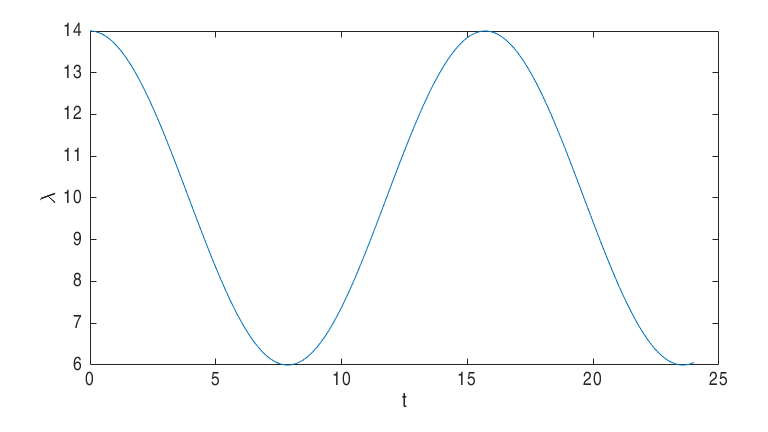

clearvars;
bin_size = 0.01;
base_rate = 10;
t = 0:bin_size:24;
lambda = base_rate+0.4*base_rate*cos(0.4*t);
arrivals = poissrnd(lambda*bin_size)';
plot(t, lambda);
xlabel('t'); ylabel('\lambda');
tight_layout([0.4, 0.4], 14);

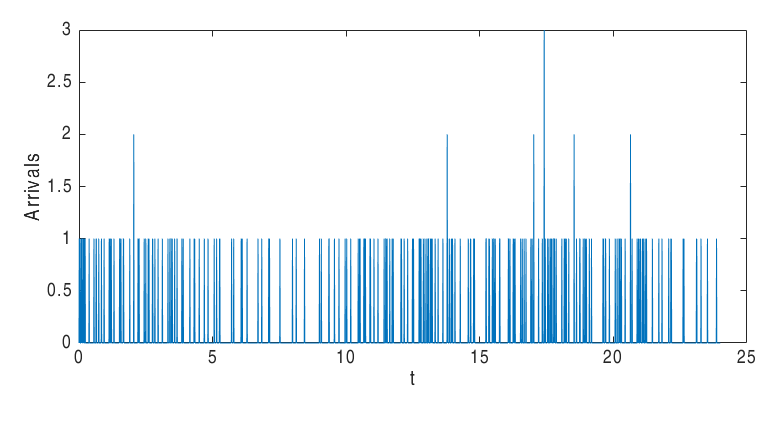

plot(t, arrivals);
xlabel('t'); ylabel('Arrivals');
tight_layout([0.4, 0.4], 14);

## Construct and show the GLM model

theta = [mu, g1, g2, g3, g4, g5]

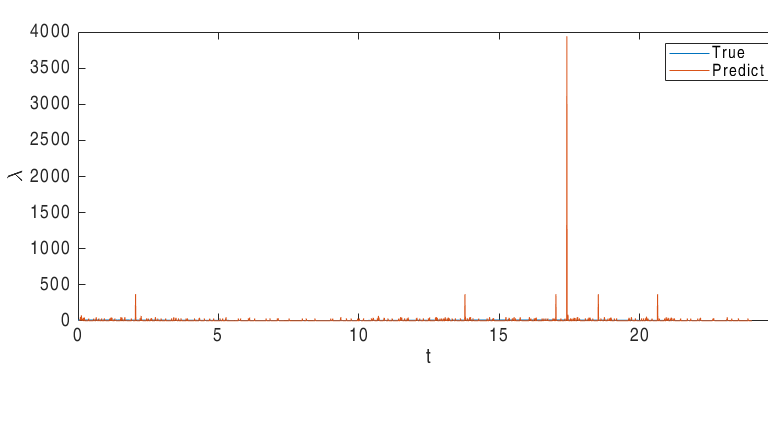

num_state = 5;
theta = [log(base_rate); zeros([num_state, 1])];
X = zeros([numel(t)-num_state+1, 1+num_state]);
for i=1:size(X,1)
    X(i,:) = [1; arrivals(i:(i+num_state-1))];
end
n = arrivals(num_state:end);

for l = 1:100
    Lam = exp(X*theta)*bin_size;
    dTheata = (X'*diag(Lam)*X)\(X')*(n-Lam);
    theta = theta + 0.1*dTheata;
end
Lam = exp(X*theta);
plot(t, lambda); hold on;
plot(t(num_state:end), Lam); hold off;
legend('True', 'Predict');
xlabel('t'); ylabel('\lambda');
tight_layout([0.4, 0.4], 14);

## Construct and show the Priorly known model.

theta = [a, b, w]

lambda = a + b * cos(w*t);

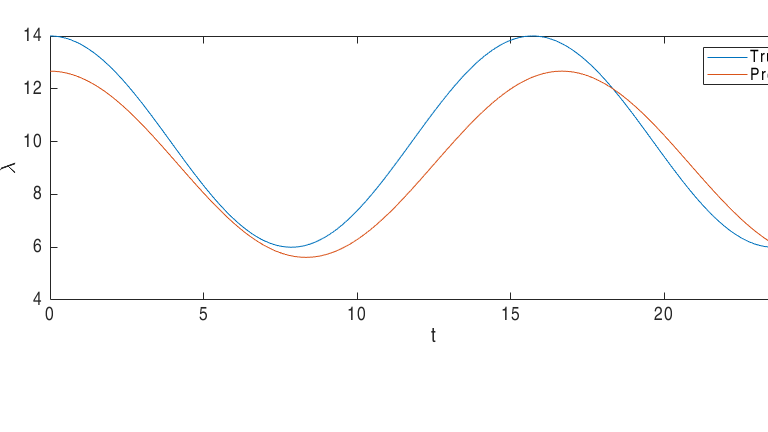

theta = [base_rate; 1.0; 0.5];

for l = 1:1000
    lr = 0.001;
    bval = cos(theta(3)*t);
    wval = -theta(2)*t.^sin(theta(3)*t);
    Lam = (theta(1)+theta(2)*cos(theta(3)*t))';
    theta(1) = theta(1) + lr*sum(arrivals./Lam - bin_size);
    theta(2) = theta(2) + lr*bval*(arrivals./Lam - bin_size);
    theta(3) = theta(3) + 0.1*lr*wval*(arrivals./Lam - bin_size);
end
Lam = (theta(1)+theta(2)*cos(theta(3)*t))';
plot(t, lambda); hold on;
plot(t, Lam); hold off;
legend('True', 'Predict');
xlabel('t'); ylabel('\lambda');
tight_layout([0.4, 0.4], 14);